sys = tf(10,[1 1]);

t = linspace(-.1,3,1000);
sys_cl = feedback(sys,1);
y = lsim(sys_cl,3*(t>=0),t);

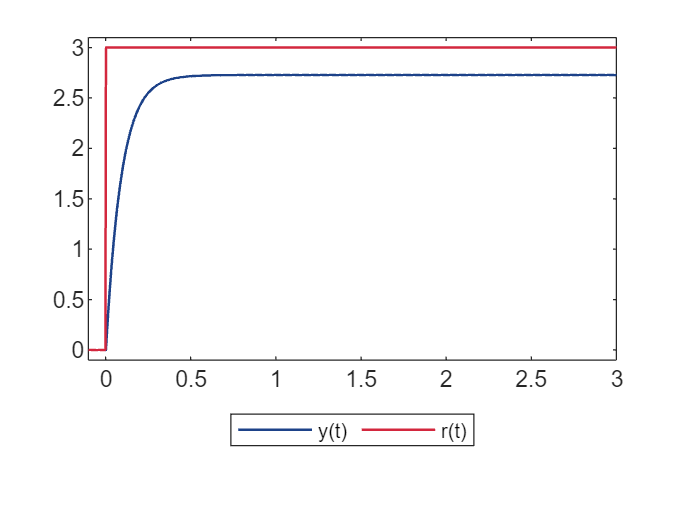

plot(t,y,'LineWidth',1,'Color',[29,66,137]/255)
hold on
plot(t,3*(t>=0),'LineWidth',1,'Color',[211,39,62]/255)
legend('y(t)','r(t)','Location', 'southoutside',...
    'Orientation','horizontal')
axis([t(1) t(end) min(y)-0.1 3.1])
hold off

sys = tf([1 2],conv([1 1],[1,5]));
D = tf(50,[1 0]);

t = linspace(-.1,3,1000);
sys_cl = feedback(sys*D,1);
y = lsim(sys_cl,t.*(t>=0),t);

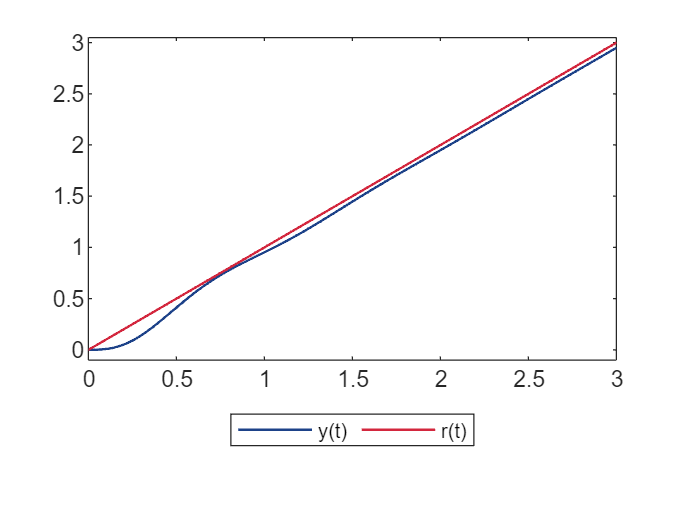

plot(t,y,'LineWidth',1,'Color',[29,66,137]/255)
hold on
plot(t,t,'LineWidth',1,'Color',[211,39,62]/255)
legend('y(t)','r(t)','Location', 'southoutside',...
    'Orientation','horizontal')
axis([t(1) t(end) min(y)-0.1 max(y)+0.1])
hold off

sys = tf(10,[1 5]);
K = 24.5;
H = tf(2,[1 2]);
sys_cl = feedback(K*sys,H);

t = linspace(-.1,2,1000);
y = lsim(sys_cl,1*(t>=0),t);

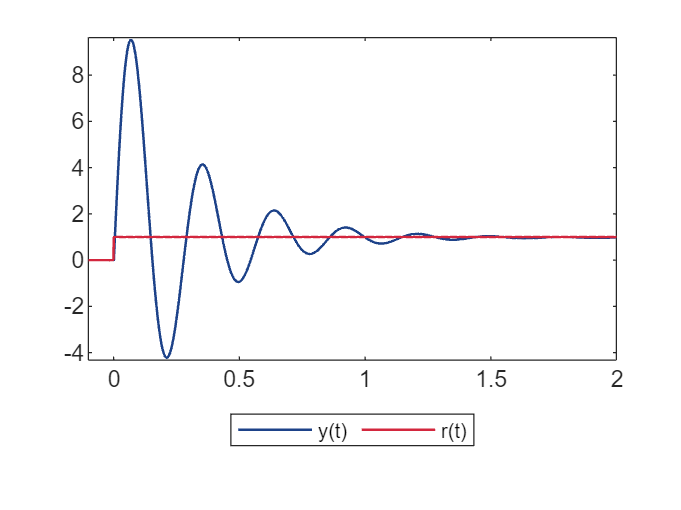

plot(t,y,'LineWidth',1,'Color',[29,66,137]/255)
hold on
plot(t,1*(t>=0),'LineWidth',1,'Color',[211,39,62]/255)
legend('y(t)','r(t)','Location', 'southoutside',...
    'Orientation','horizontal')
axis([t(1) t(end) min(y)-0.1 max(y)+0.1])
hold off